# SIS Model

#### The Model

The SIS model in epidemology is one that is determined to describe the behavior of an infectious disease where the people that were infected do not confer immunity after recovery. 

The mathematical model compartmentalizes each set of people into two groups: suceptible (S) and infectious (I). Suceptible people are those who can potentially get infected and infectious those who can potentially infect suceptible people. Since there is no immunity granted, people who just recovered can be instantly catalogued as suceptible in order to simplify the model. The total number of the populations is assumed to not change in time and is given by:

$N=S_0+I_0=S(t)+I(t)$,

where $S_0$ and $I_0$ are the initial conditions for the suceptible and infected populations repectively. Usually most of the population will lie in the suceptible compartment and will enventually flow to the infectious one. Since it is assumed no immunity is obtained ater recovery, the $I$ population will return to the $S$ compartment.

The image below shows the compartment diagram for the two variables and describes the flow between them.

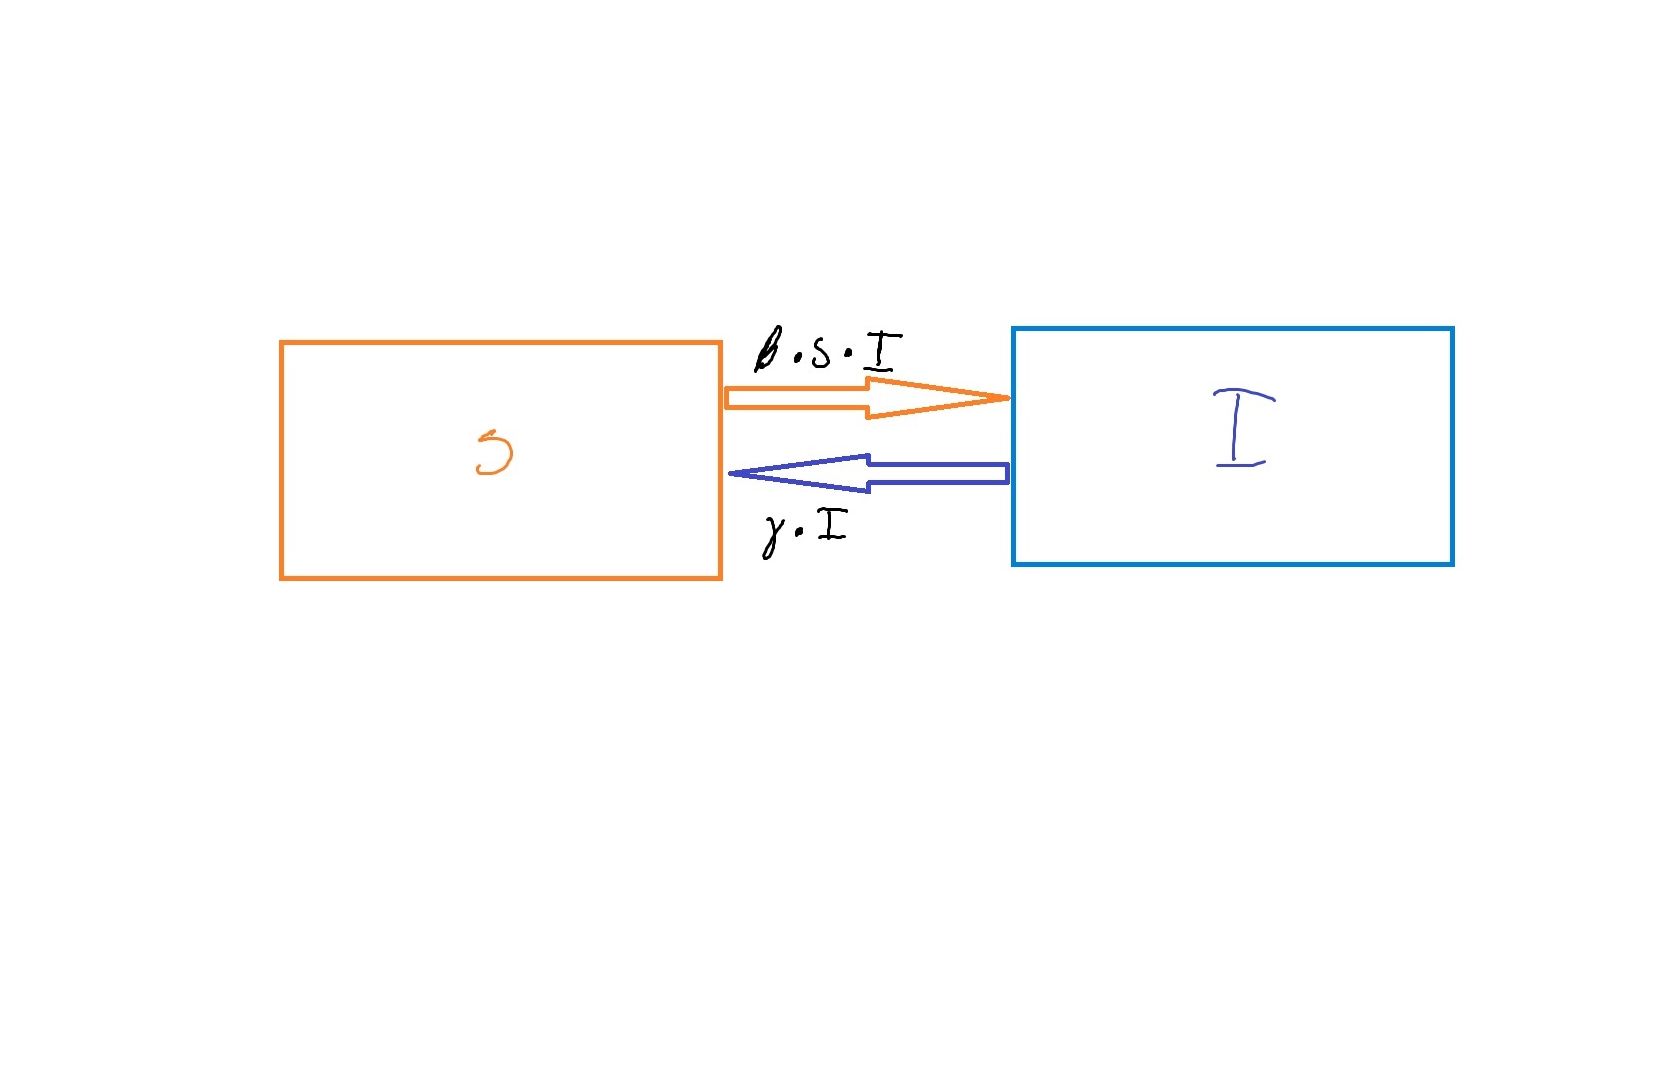

imshow('SIS_Block_Diagram.jpg')

The aim of this model is to describe how individuals flow from each compartment to another based on a few variables and through the course o time, and can be done so based on the following differential equations:

$\frac{dS}{dt}=\gamma*I-\beta*I*S

$,

$\frac{dI}{dt}=\beta*I*S-\gamma*I$.

Parameters:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

- $\gamma$ corresponds to the recovery rate. Its value relies on the virulence or pathogenicity of the organism responsible for the disease as well as the average physical and mental conditions of the population, which can also affect how drammatically an individual will experience related symptoms.

## Solution with Euler method

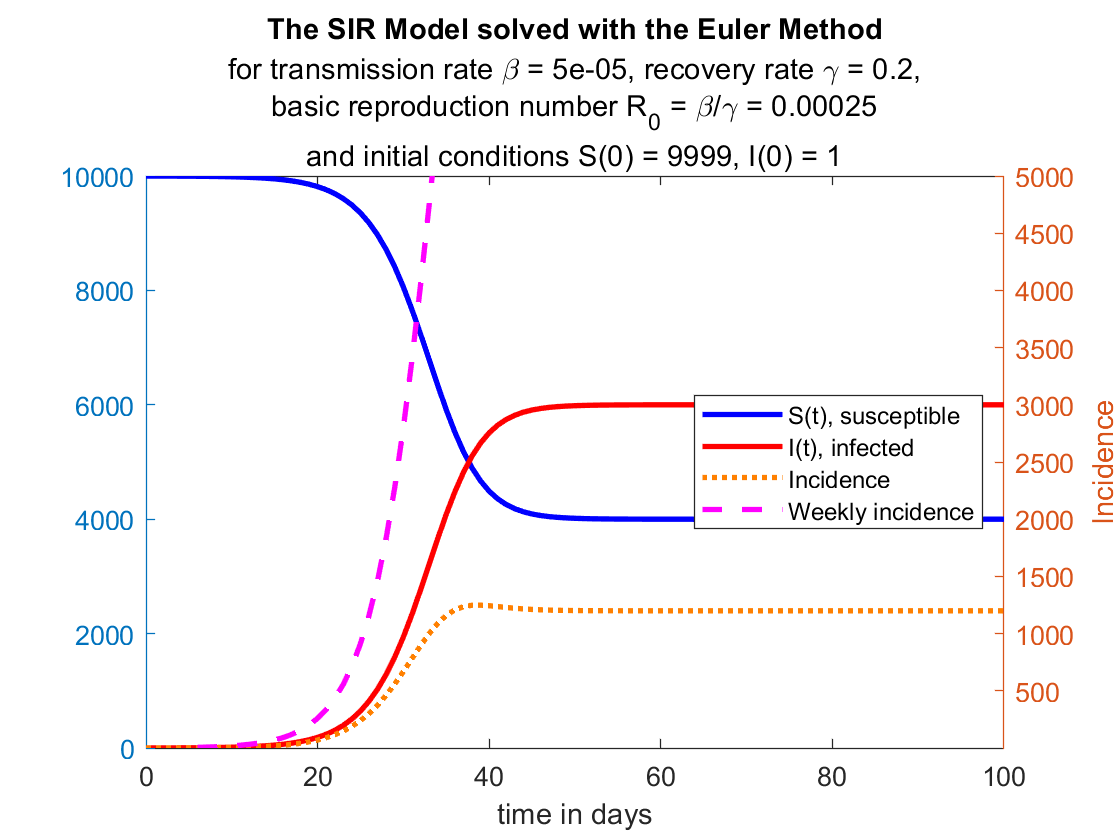

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
N=S(1)+I(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;
gamma = 0.2 ;

R_0=beta/gamma;


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    S(t+1) = S(t) - beta*I(t)*S(t)+ gamma*I(t);   
    I(t+1) = I(t) + (beta*I(t)*S(t)) - gamma*I(t);   
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SIR Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1))]})
legend('S(t), susceptible', 'I(t), infected','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;